# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

Copyright 2023 The MathWorks, Inc.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'docx';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING; %#ok<GVMIS> 
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\C_project\\ParkingMeterProject\\x64\\Release\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp
--> Processing the test case #1: Straight Ticket Purchase...


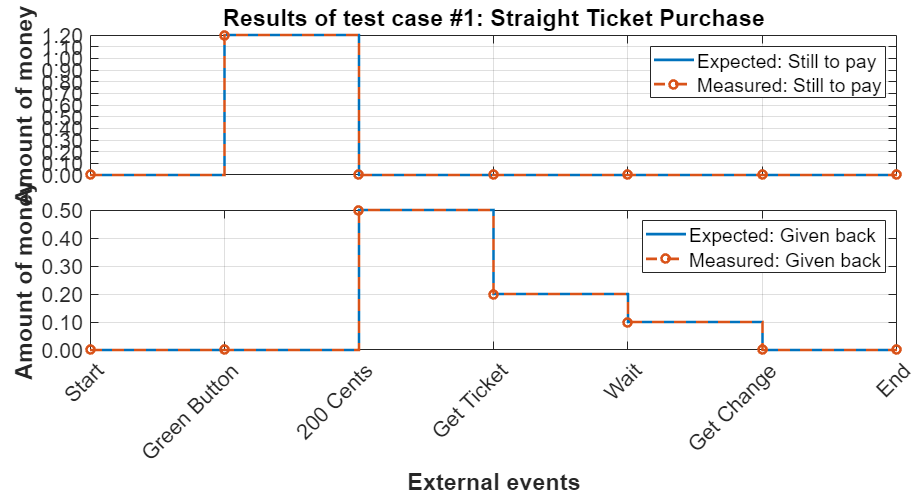


[Terse] Diagnostic logged (2022-10-16 18:50:16):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_24373f92-ac4c-450d-b2c5-579bad83ecd8.fig
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_24373f92-ac4c-450d-b2c5-579bad83ecd8.png
--------------------------------------------------------------------------------
.--> Processing the test case #2: Biggest Change On Ticket Purchase...


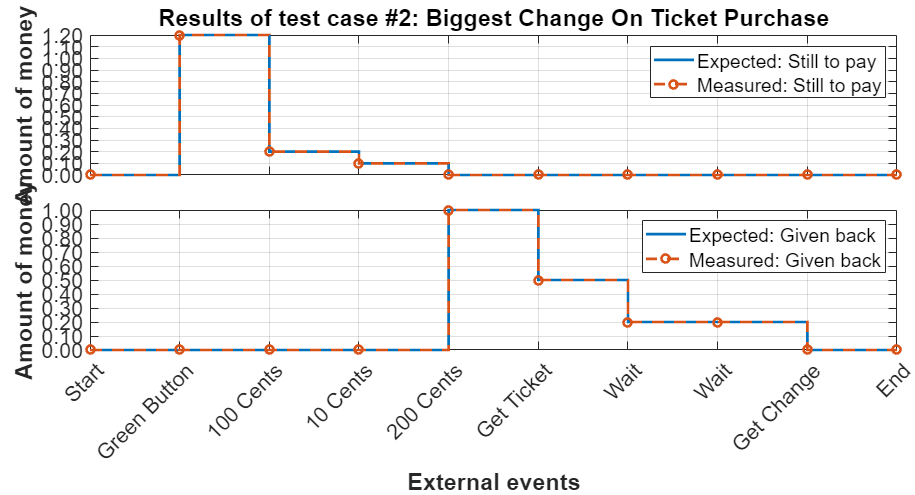


[Terse] Diagnostic logged (2022-10-16 18:50:39):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_2c85ecc4-4334-499d-b4e0-313a3137ebeb.fig
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_2c85ecc4-4334-499d-b4e0-313a3137ebeb.png
--------------------------------------------------------------------------------
.--> Processing the test case #3: Cancel Ticket Purchase...


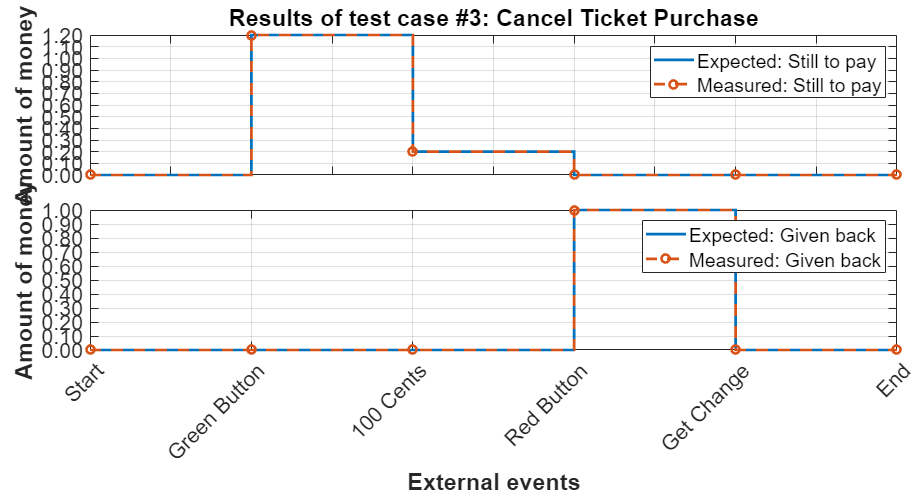


[Terse] Diagnostic logged (2022-10-16 18:50:58):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_e7794a3a-3446-49db-8c14-cf395c429b0d.fig
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_e7794a3a-3446-49db-8c14-cf395c429b0d.png
--------------------------------------------------------------------------------
.--> Processing the test case #4: 50 Cents Incremental Ticket Purchase...


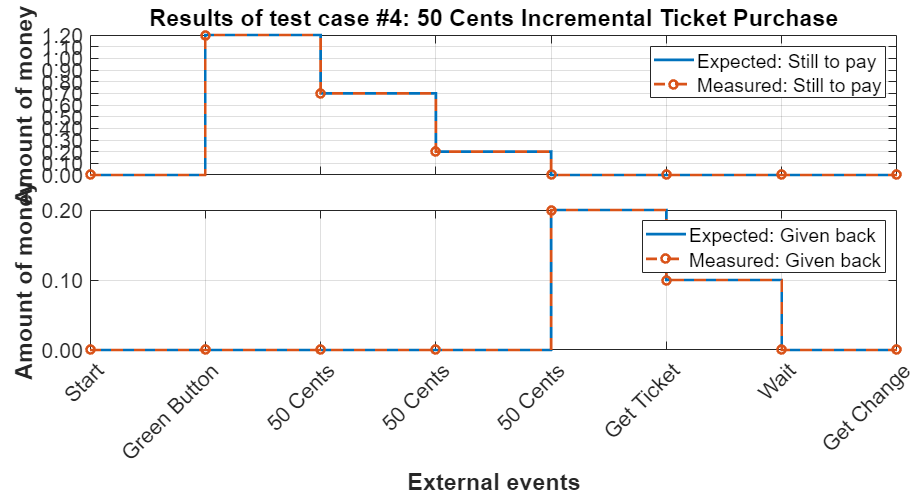


[Terse] Diagnostic logged (2022-10-16 18:51:23):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_4165232f-e4c4-4acd-8f9c-6db6523c1cb5.fig
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_4165232f-e4c4-4acd-8f9c-6db6523c1cb5.png
--------------------------------------------------------------------------------
.--> Processing the test case #5: 20 Cents Incremental Ticket Purchase...


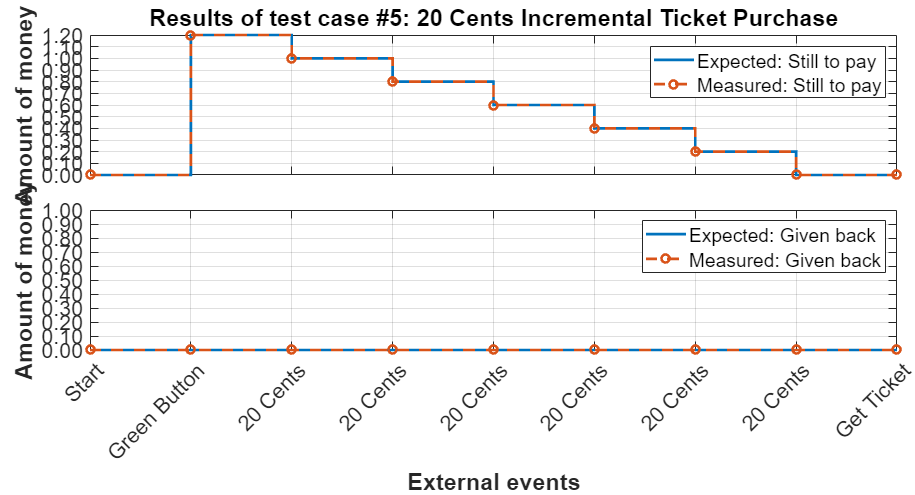


[Terse] Diagnostic logged (2022-10-16 18:51:53):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_00638426-e52d-4f6a-bb5c-fa1c05b2d2db.fig
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_00638426-e52d-4f6a-bb5c-fa1c05b2d2db.png
--------------------------------------------------------------------------------
.--> Processing the test case #6: 10 Cents Incremental Ticket Purchase...


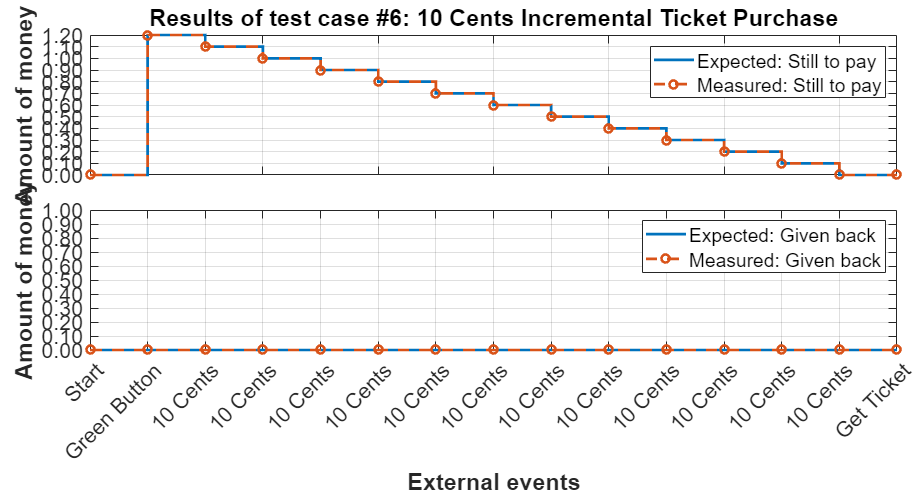


[Terse] Diagnostic logged (2022-10-16 18:52:35):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_f58515d2-b62d-4acf-bf48-29eb707e6895.fig
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_f58515d2-b62d-4acf-bf48-29eb707e6895.png
--------------------------------------------------------------------------------
.--> Processing the test case #7: Fully Empty And Reload CashBox...


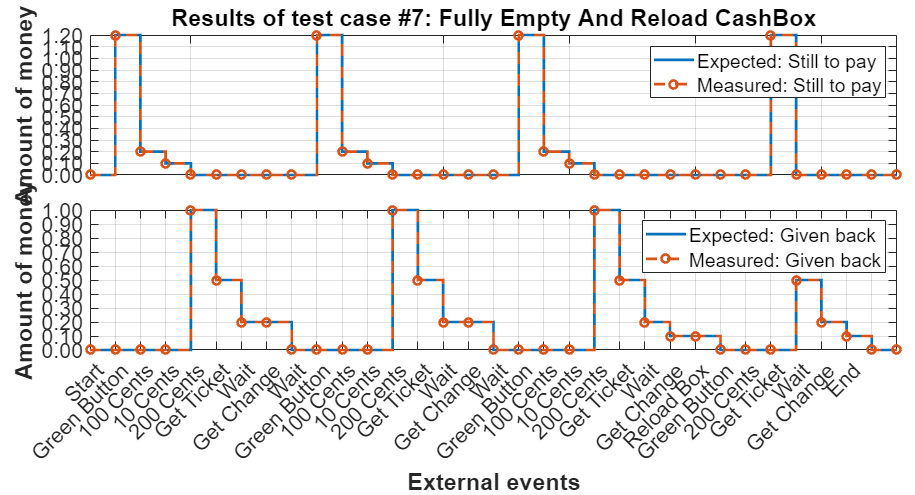


[Terse] Diagnostic logged (2022-10-16 18:53:35):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_4def2c35-c157-4e02-9e1f-c5421b2b2f5c.fig
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_4def2c35-c157-4e02-9e1f-c5421b2b2f5c.png
--------------------------------------------------------------------------------
.--> Processing the test case #8: Switch Off The Low Level Application...


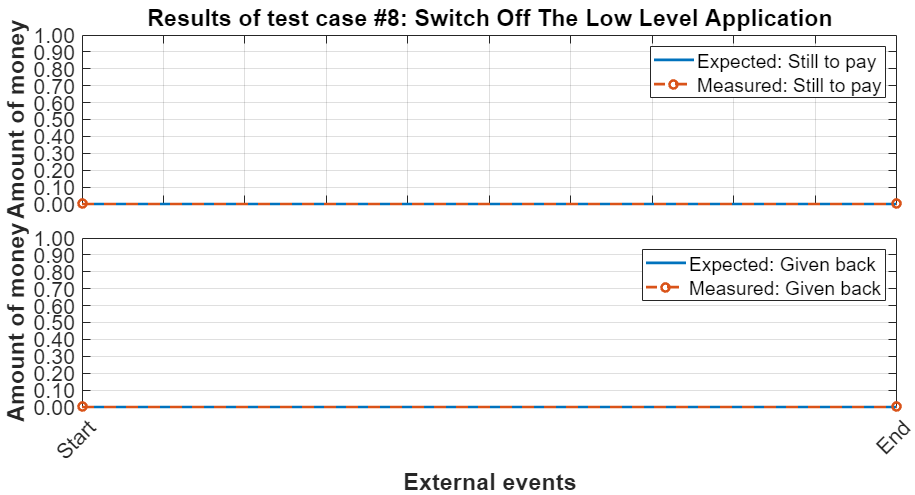


[Terse] Diagnostic logged (2022-10-16 18:53:49):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_7324b390-15df-41d2-8779-75d447f19e8e.fig
--> C:\Users\sebas\AppData\Local\Temp\2f317fdb-cb6e-4d9a-9ee6-83c53be28a27\Figure_7324b390-15df-41d2-8779-75d447f19e8e.png
--------------------------------------------------------------------------------
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.
    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.docx
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tp7fd2b07c_81dd_4e90_8517_25bb04cd429c\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                             Name                             Passed    Failed    Incomplete    Duration      Details   
    ______________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_StraightTicketPurchase'           }    true      false       false        17.718     {1×1 struct}
    {'TestApp/testCase_BiggestChangeOnTicketPurchase'    }    true      false       false        24.202     {1×1 struct}
    {'TestApp/testCase_CancelTicketPurchase'             }    true      false       false          17.6     {1×1 struct}
    {'TestApp/testCase_050CentsIncrementalTicketPurchase'}    true      false       false        25.927     {1×1 struct}
    {'TestApp/testCase_020CentsIncrementalTicketPurchase'}    true   